Load the Signal

[signal,fs]=audioread("s3.wav");
signal, fs

signal =     0.0312
    0.0210
    0.0117
    0.0176
    0.0122
    0.0059
    0.0088
    0.0112
    0.0049
    0.0054


fs = 12500

Visualizing the Signal

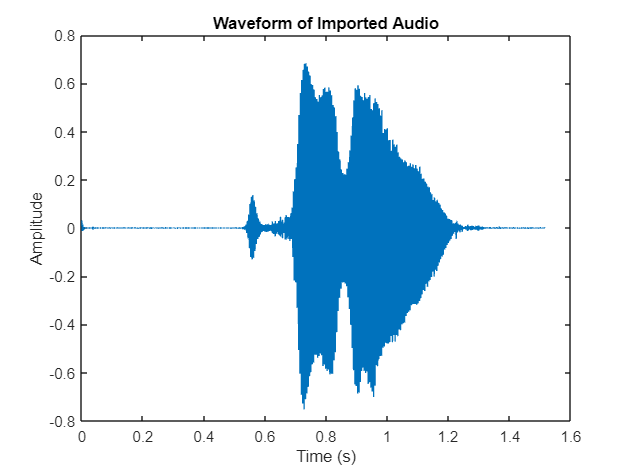

t = (0:length(signal)-1)/fs;   % Time axis
plot(t, signal);
xlabel('Time (s)');
ylabel('Amplitude');
title('Waveform of Imported Audio');

Preemphasising

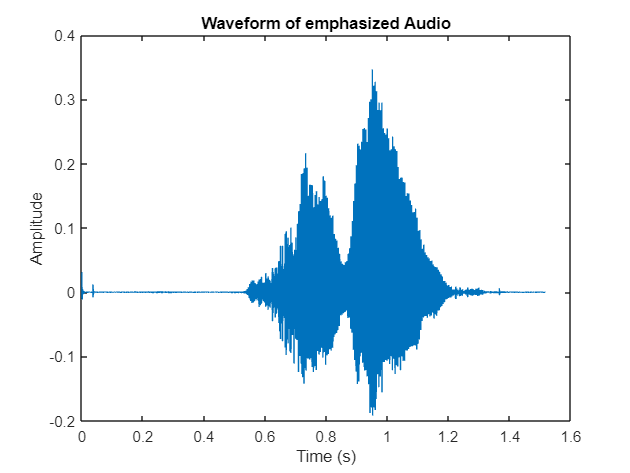

alpha = 0.97;
emphasized = preemphasis(signal, alpha);
plot(t, emphasized);
xlabel('Time (s)');
ylabel('Amplitude');
title('Waveform of emphasized Audio');

Framing

frame_length = 256;
hop_size=100;
frames = frame_signal(emphasized, frame_length, hop_size);
frames

frames =     0.0312    0.0013   -0.0005         0   -0.0005   -0.0005         0    0.0005   -0.0000         0   -0.0005         0    0.0005   -0.0005         0    0.0000   -0.0005    0.0010   -0.0005    0.0005    0.0005   -0.0000   -0.0000   -0.0005         0   -0.0005         0    0.0004    0.0000   -0.0005    0.0010    0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0000   -0.0000   -0.0000         0    0.0005         0    0.0005   -0.0005         0   -0.0005   -0.0005         0         0
   -0.0093    0.0004    0.0005         0    0.0005   -0.0010   -0.0005   -0.0005   -0.0000         0    0.0005   -0.0005   -0.0000   -0.0000         0    0.0000    0.0005         0         0         0    0.0005   -0.0000    0.0010         0    0.0005   -0.0010   -0.0005    0.0005   -0.0005   -0.0005   -0.0005    0.0005   -0.0005    0.0005   -0.0000   -0.0010         0   -0.0000    0.0005    0.0010         0         0   -0.0005   -0.0005   -0.0005         0   -0.0000    0.0005         0

Applying Hamming Window

windowed_frames=apply_window(frames);

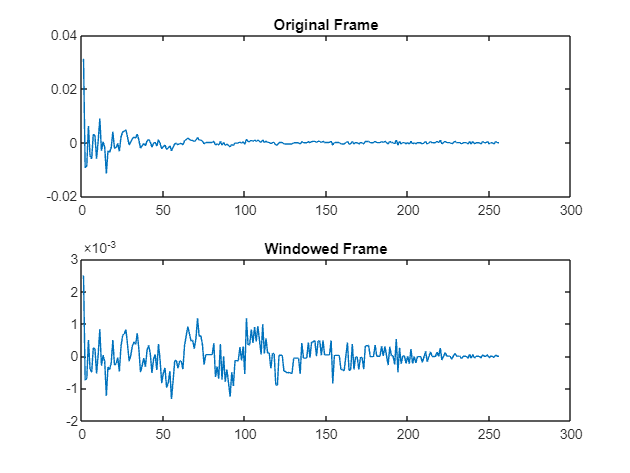

frameIdx = 1;
subplot(2,1,1);
plot(frames(:, frameIdx));
title('Original Frame');

subplot(2,1,2);
plot(windowed_frames(:, frameIdx));
title('Windowed Frame');

[frame_length_windowed,number_of_frames]=size(windowed_frames);
frame_length_windowed

frame_length_windowed = 256

number_of_frames

number_of_frames = 187

Compute the Power Spectrum

nfft = 512;
power_spectrum = compute_power_spectrum(windowed_frames, nfft)

power_spectrum =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000  

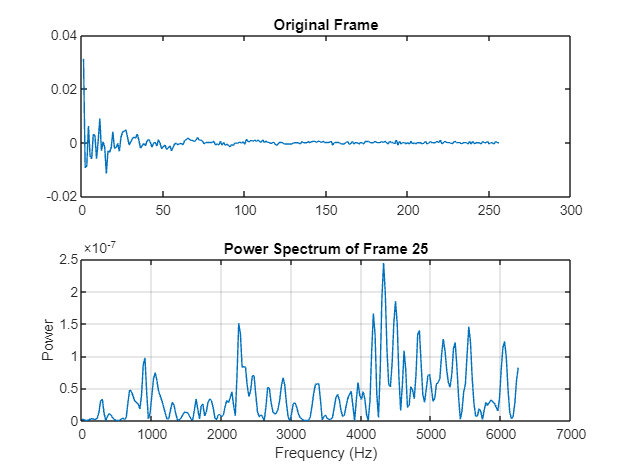

frameIdx = 25;
freq_axis = (0:nfft/2) * fs / nfft;

plot(freq_axis, power_spectrum(:, frameIdx));
xlabel('Frequency (Hz)');
ylabel('Power');
title(sprintf('Power Spectrum of Frame %d', frameIdx));
grid on;

Creating Mel Filter Bank and Applying

Num_of_Mel_filters=26;
Melbank_filter=melfb(Num_of_Mel_filters,nfft,fs)

Melbank_filter =          0    0.2000    0.4000    0.2667    0.1333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.1111    0.2222    0.3333    0.2222    0.1111         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

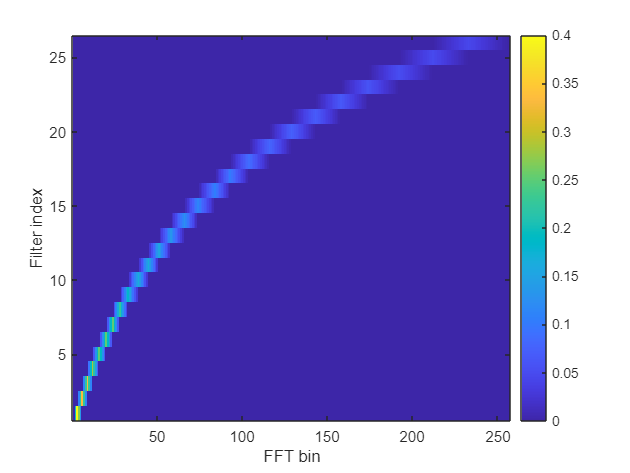

figure;
imagesc(Melbank_filter);
axis xy;
xlabel("FFT bin")
ylabel("Filter index")
colorbar;

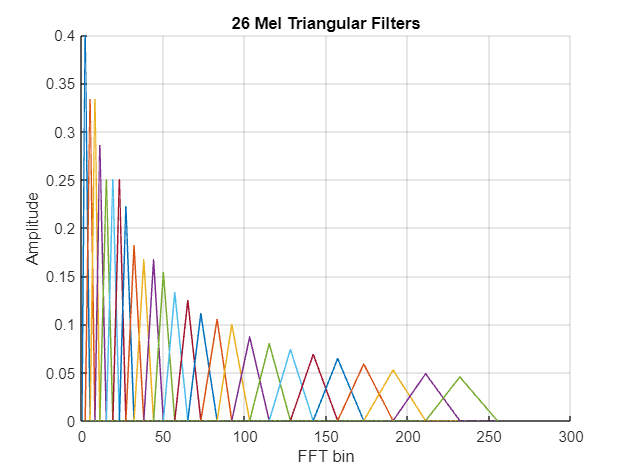

figure;
hold on;

[num_filters, num_bins] = size(Melbank_filter);

for m = 1:num_filters
    plot(0:num_bins-1, Melbank_filter(m,:), 'LineWidth', 1);
end

xlabel('FFT bin');
ylabel('Amplitude');
title('26 Mel Triangular Filters');
grid on;
hold off;

mel_energies = apply_mel_filterbank(power_spectrum, fs, nfft, num_filters)

mel_energies =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    

Mel Energy

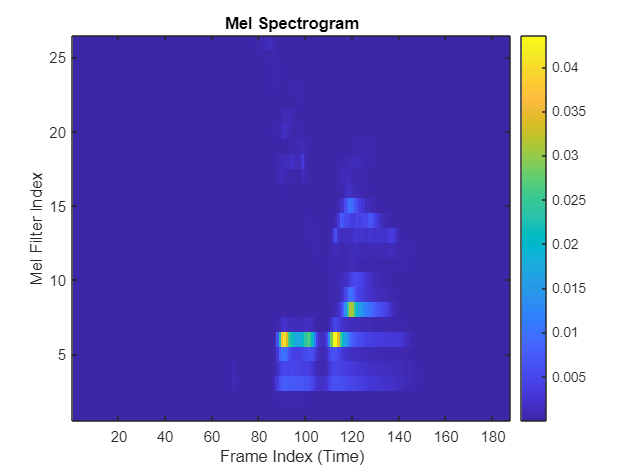

% Plot as an image
imagesc(mel_energies);

% Adjust axes
axis xy;   % put low frequencies at bottom
xlabel('Frame Index (Time)');
ylabel('Mel Filter Index');
title('Mel Spectrogram');
colorbar;

Correlation across Frames

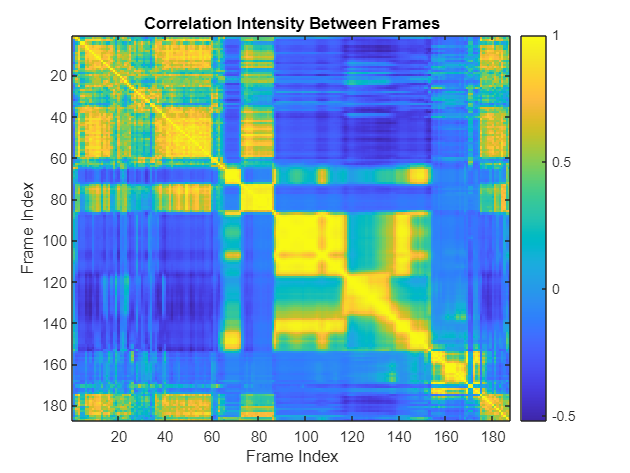

R = corrcoef(mel_energies);   % correlation across frames
imagesc(R);
colorbar;
xlabel('Frame Index');
ylabel('Frame Index');
title('Correlation Intensity Between Frames');

Apply Log

log_mel = apply_log(mel_energies)

log_mel =   -18.5033  -20.7790  -20.5791  -21.9428  -21.1276  -22.0190  -20.8916  -22.1367  -20.9081  -21.8278  -21.0336  -21.0742  -21.1882  -21.4145  -21.4849  -21.4618  -21.2690  -21.8744  -21.6749  -20.8918  -21.7892  -20.8835  -21.2485  -21.0667  -20.7607  -21.7918  -21.5720  -21.1959  -21.6906  -21.4682  -21.1898  -21.5424  -20.3347  -21.9169  -20.7963  -21.8161  -21.9253  -20.7714  -21.1324  -20.7061  -21.9493  -20.8569  -21.5630  -21.7435  -21.2283  -21.6308  -21.0681  -21.4238  -21.1720  -21.8692
  -17.4673  -21.3604  -21.6382  -22.7959  -23.6812  -23.6670  -23.4893  -21.9964  -21.1587  -19.9847  -20.1975  -19.6911  -20.7575  -19.9530  -20.2931  -20.4312  -22.1796  -21.7389  -22.8201  -20.3652  -19.6011  -20.3178  -21.9722  -21.4743  -19.9602  -20.7072  -21.0771  -21.3024  -21.0956  -21.1149  -19.5168  -20.5945  -21.4177  -19.2293  -20.1679  -19.9034  -20.7455  -19.6949  -20.1655  -21.6438  -23.1054  -22.1681  -23.2596  -22.9458  -23.3788  -22.4122  -20.4734  -22.4907  -20.945

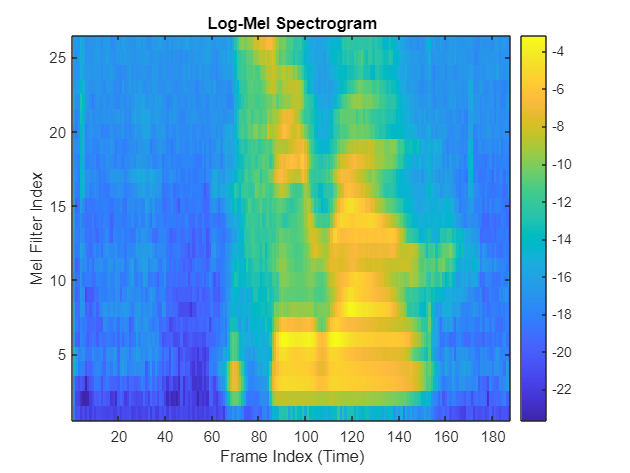

% Plot as an image
imagesc(log_mel);

% Adjust axes
axis xy;   % put low frequencies at bottom
xlabel('Frame Index (Time)');
ylabel('Mel Filter Index');
title('Log-Mel Spectrogram');
colorbar;

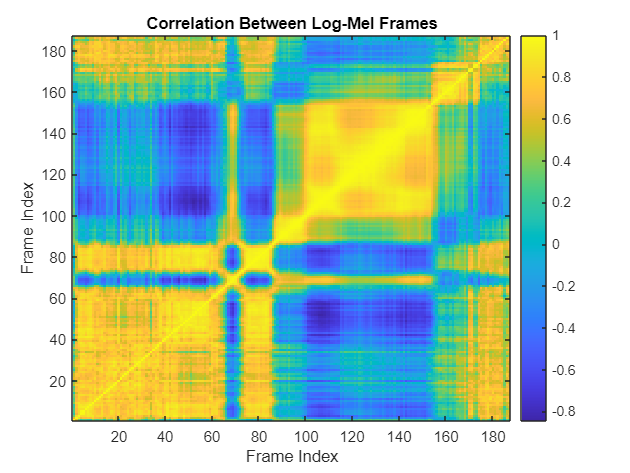

R_log = corrcoef(log_mel);

imagesc(R_log);
axis xy;
colorbar;
xlabel('Frame Index');
ylabel('Frame Index');
title('Correlation Between Log-Mel Frames');

Apply Fourier Cosine transform

num_coeffs =13;
mfcc = apply_dct(log_mel, num_coeffs)

mfcc =   -84.6655  -94.0774  -94.1807  -83.6803  -87.5592  -95.7119  -94.7470  -94.8710  -93.8439  -92.4547  -92.8908  -91.8829  -93.2149  -92.0841  -90.7911  -90.8329  -92.0257  -91.9928  -91.0741  -92.0002  -90.9532  -90.3386  -92.1147  -90.9522  -91.0678  -90.5216  -90.0230  -88.5904  -88.2939  -88.3179  -86.7738  -88.8391  -89.0519  -88.6610  -89.6927  -89.9638  -91.1541  -91.4388  -93.0795  -92.6522  -95.9280  -95.5276  -95.2120  -96.1311  -95.9943  -97.5302  -95.8622  -96.8124  -96.2405  -96.5910
    0.2524   -4.0828   -5.6821  -10.5412   -8.8929   -7.3801   -7.1709   -6.6387   -4.7155   -4.0703   -4.7056   -3.5703   -4.3404   -4.1128   -3.2389   -3.6398   -4.6348   -3.6508   -3.1817   -4.7392   -2.6824   -3.1464   -3.0588   -3.6768   -4.2494   -4.2811   -4.5225   -3.6781   -4.3889   -4.5185   -3.6544   -5.0913   -3.9586   -2.2003   -4.2415   -4.0029   -5.3564   -5.3617   -5.5833   -4.9738   -6.8252   -7.6794   -6.1303   -7.6804   -7.5763   -8.7826   -6.0342   -8.2715   -7.6041  

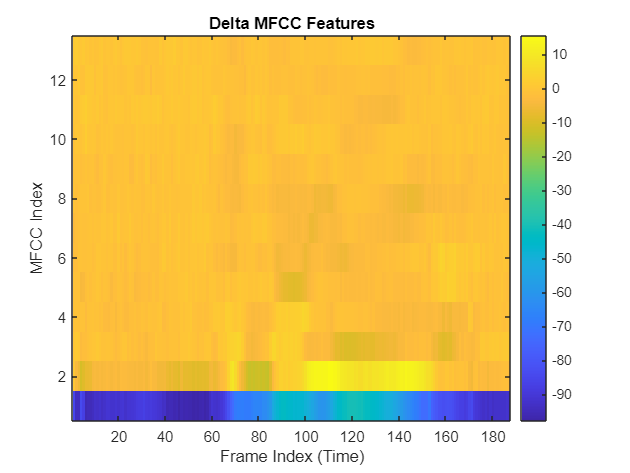

% Plot as an image
imagesc(mfcc)
% Adjust axes
axis xy;   % put low frequencies at bottom
xlabel('Frame Index (Time)');
ylabel('MFCC Index');
title('Delta MFCC Features');
colorbar;

Apply Delta Fourier Cosine transform

delta_mfcc = compute_delta(mfcc)

delta_mfcc =    -2.8442   -0.7545    0.4610    0.3352   -1.3164   -2.9569   -1.1728    0.7417    0.6129    0.6929    0.1830    0.0417    0.3998    0.4524    0.3629   -0.1052   -0.1726   -0.1383    0.2138    0.3429   -0.0420    0.0935   -0.0843    0.0681    0.4614    0.5768    0.7479    0.6136    0.6771    0.1023   -0.2037   -0.2964   -0.5660   -0.2890   -0.5507   -0.7017   -0.8249   -0.7302   -1.0761   -1.1026   -0.7140   -0.6242   -0.0736   -0.4787   -0.2700   -0.1230    0.0225    0.1500   -0.1499   -0.2340
   -1.6204   -2.7521   -2.4749   -0.9806    0.0183    0.9527    0.9096    0.9075    0.7499    0.6147    0.1250    0.0280    0.2391    0.0962   -0.0116   -0.0472    0.0103   -0.0746    0.2816    0.1508    0.1839    0.1749   -0.3664   -0.3460   -0.3532   -0.0276    0.0324   -0.0341    0.0896   -0.2092    0.0288    0.4332    0.1717    0.1894   -0.4598   -0.7438   -0.4042   -0.2169   -0.2550   -0.5877   -0.3800   -0.4718   -0.1503   -0.3652   -0.0910    0.0360    0.0455   -0.0301   -0.

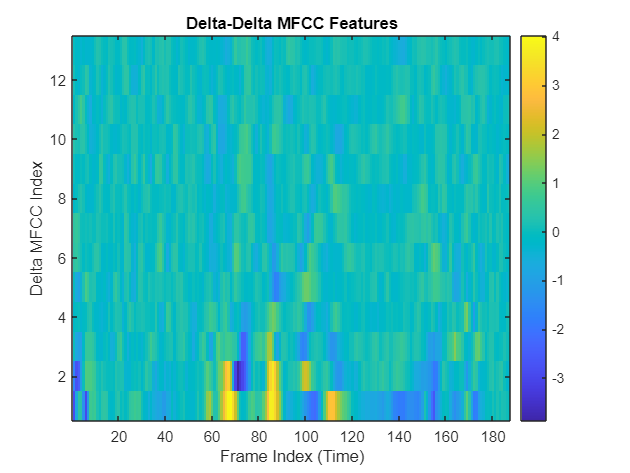

% Plot as an image
imagesc(delta_mfcc)
% Adjust axes
axis xy;   % put low frequencies at bottom
xlabel('Frame Index (Time)');
ylabel('Delta MFCC Index');
title('Delta-Delta MFCC Features');
colorbar;

Apply Delta Delta Fourier Cosine transform

delta_delta_mfcc = compute_delta(delta_mfcc)

delta_delta_mfcc =     0.8700    0.9664    0.4145   -0.6182   -0.6560    0.0957    0.7557    0.9085    0.2663   -0.1830   -0.1077   -0.0264    0.0771   -0.0331   -0.1702   -0.1717   -0.0331    0.1283    0.0742    0.0208   -0.0846   -0.0592    0.0981    0.1512    0.2173    0.1378    0.0468   -0.1020   -0.2415   -0.2701   -0.2885   -0.1145   -0.0687   -0.0795   -0.0930   -0.1157   -0.1079   -0.1053   -0.0151    0.0574    0.2483    0.1888    0.1034    0.0806    0.0548    0.1550    0.0513   -0.0394   -0.0992   -0.0983
   -0.2841    0.0425    0.5049    0.9903    0.8702    0.4667    0.1418   -0.0836   -0.1862   -0.2384   -0.1608   -0.0923   -0.0205   -0.0401   -0.0601   -0.0320    0.0559    0.0667    0.0572    0.0401   -0.1272   -0.1544   -0.1595   -0.0392    0.1116    0.1009    0.0879   -0.0306   -0.0182    0.0874    0.0807    0.0940   -0.1221   -0.2985   -0.2085   -0.0757    0.0937    0.0461   -0.0322   -0.0635    0.0325    0.0675    0.0684    0.1075    0.0793    0.0807   -0.0714   -0.0840

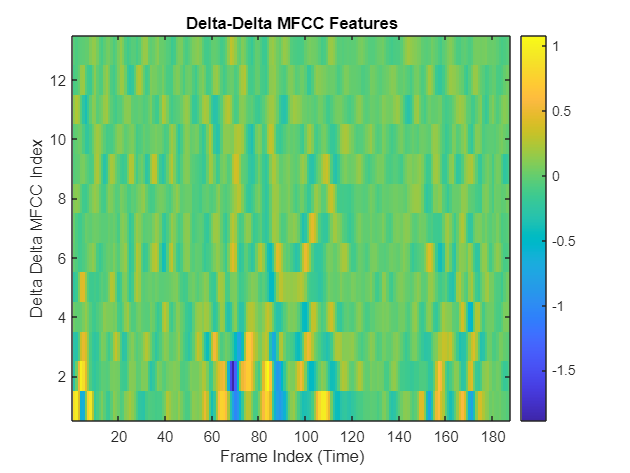

% Plot as an image
imagesc(delta_delta_mfcc)
% Adjust axes
axis xy;   % put low frequencies at bottom
xlabel('Frame Index (Time)');
ylabel('Delta Delta MFCC Index');
title('Delta-Delta MFCC Features');
colorbar;

Final Feature Matrix

Final_feature_vector=[mfcc;delta_mfcc;delta_delta_mfcc]

Final_feature_vector =   -84.6655  -94.0774  -94.1807  -83.6803  -87.5592  -95.7119  -94.7470  -94.8710  -93.8439  -92.4547  -92.8908  -91.8829  -93.2149  -92.0841  -90.7911  -90.8329  -92.0257  -91.9928  -91.0741  -92.0002  -90.9532  -90.3386  -92.1147  -90.9522  -91.0678  -90.5216  -90.0230  -88.5904  -88.2939  -88.3179  -86.7738  -88.8391  -89.0519  -88.6610  -89.6927  -89.9638  -91.1541  -91.4388  -93.0795  -92.6522  -95.9280  -95.5276  -95.2120  -96.1311  -95.9943  -97.5302  -95.8622  -96.8124  -96.2405  -96.5910
    0.2524   -4.0828   -5.6821  -10.5412   -8.8929   -7.3801   -7.1709   -6.6387   -4.7155   -4.0703   -4.7056   -3.5703   -4.3404   -4.1128   -3.2389   -3.6398   -4.6348   -3.6508   -3.1817   -4.7392   -2.6824   -3.1464   -3.0588   -3.6768   -4.2494   -4.2811   -4.5225   -3.6781   -4.3889   -4.5185   -3.6544   -5.0913   -3.9586   -2.2003   -4.2415   -4.0029   -5.3564   -5.3617   -5.5833   -4.9738   -6.8252   -7.6794   -6.1303   -7.6804   -7.5763   -8.7826   -6.0342   -8.

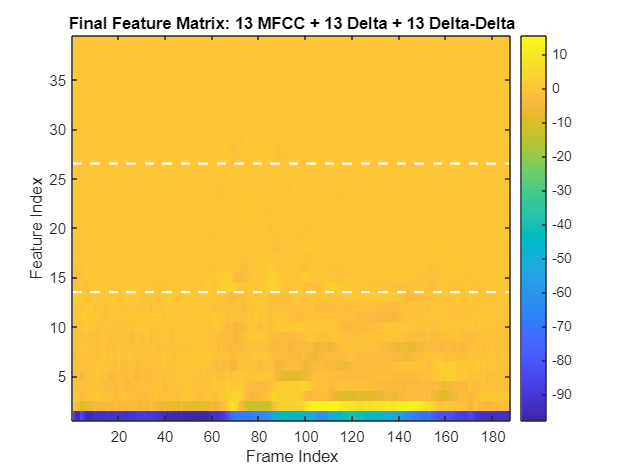

imagesc(Final_feature_vector);
axis xy;
xlabel('Frame Index');
ylabel('Feature Index');
title('Final Feature Matrix: 13 MFCC + 13 Delta + 13 Delta-Delta');
colorbar;

hold on;
plot([0.5 size(Final_feature_vector,2)+0.5], [13.5 13.5], 'w--', 'LineWidth', 1.5);
plot([0.5 size(Final_feature_vector,2)+0.5], [26.5 26.5], 'w--', 'LineWidth', 1.5);
hold off;

matlab.internal.liveeditor.openAndConvert('Final_assemble.mlx', 'Final_assemble.pdf');